Probabilidade de 3 peças da amostra serem defeituosas

Simulação

prob=0.3;
n_pecas=5;

matriz_producao=rand(5,10000)<prob;
defeituosas_3_em_cada_5=sum(matriz_producao)==3;
numero_de_pecas_defeituosas=cumsum(defeituosas_3_em_cada_5);
resultado=numero_de_pecas_defeituosas(end)/10000

resultado = 0.1286

Analiticamente

prob_using_combination= nchoosek(n_pecas,3)*prob^3*(1-prob)^(n_pecas-3)

prob_using_combination = 0.1323

Probabilidade de, no máximo, 2 das peças da amostra serem defeituosas

Simulação

prob=0.3;
n_pecas=5;

matriz_producao=rand(5,10000)<prob;
defeituosas_maximo_2_em_cada_5=sum(matriz_producao)<=2;
numero_de_pecas_defeituosas=cumsum(defeituosas_maximo_2_em_cada_5);
resultado=numero_de_pecas_defeituosas(end)/10000

resultado = 0.8374

Analiticamente

prob_using_combination1= nchoosek(n_pecas,2)*prob^2*(1-prob)^(n_pecas-2);

prob_using_combination2= nchoosek(n_pecas,1)*prob^1*(1-prob)^(n_pecas-1);

prob_using_combination3= nchoosek(n_pecas,0)*prob^0*(1-prob)^(n_pecas);

prob_using_combination=prob_using_combination1+prob_using_combination2+prob_using_combination3

prob_using_combination = 0.8369

Histograma

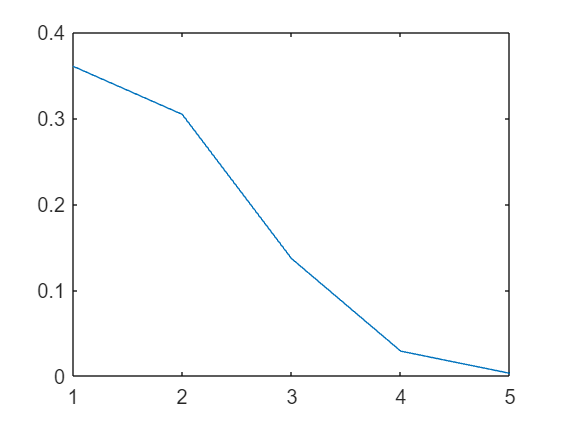

prob=0.3;
n_pecas=5;
probabilidade_de_x_pecas_serem_defeituosas_em_cada_5=zeros(1,5);

for x = 1:5
    matriz_producao=rand(5,10000)<prob;
    defeituosas_maximo_x_em_cada_5=sum(matriz_producao)==x;
    numero_de_pecas_defeituosas=cumsum(defeituosas_maximo_x_em_cada_5);
    resultado=numero_de_pecas_defeituosas(end)/10000;
    probabilidade_de_x_pecas_serem_defeituosas_em_cada_5(x)=resultado;
end

plot(1:5,probabilidade_de_x_pecas_serem_defeituosas_em_cada_5)

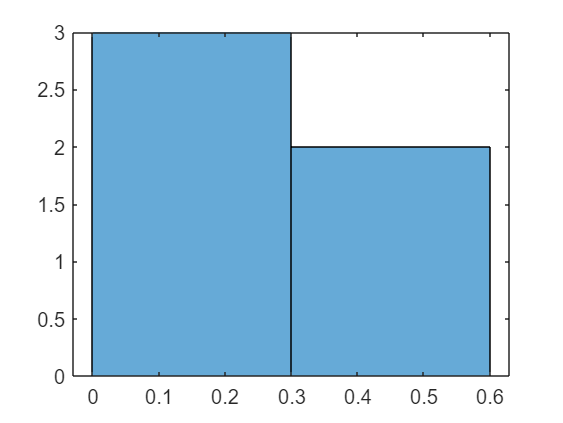

histogram(probabilidade_de_x_pecas_serem_defeituosas_em_cada_5)